clear; close all; clc; % initializes workspace, figures, and command window

# 分散最大化と分散共分散行列の固有ベクトル，固有値

## 本章の目的

前章では，多次元空間に広がる多変量データにおいて，任意の方向の分散の定式化しました．すなわち，任意の単位ベクトル$u$が示す方向における分散$S$は，データ行列$X$の分散共分散行列を用いると，


$$S=\left(u,\mathit{Vu}\right)$$


と表すことができることを解説しました．また，二変量データを例にして，その分散$S$を任意の単位ベクトル$u=\left\lbrack \begin{array}{c}
{\mathrm{u}}_1 \\
{\mathrm{u}}_2 
\end{array}\right\rbrack$の関数としてグラフにしました．その際，データがもっとも広がる方向において分散$S$が最大になることを図を用いて確認しました．

前章で述べたように，PCAによる次元圧縮において，最初の課題は「データの分散が最大限に含まれる主軸（第一主成分）を探す」ということです．じつはこの主軸は分散共分散行列の固有ベクトルとして求めることができます．

本章では，データの分散の最大化と分散共分散行列の固有ベクトルおよび固有値の関係について具体例を通して紹介していきます．具体的には，

- PCAの主成分係数が，分散共分散行列$V$の固有ベクトルと一致する

- PCAの主成分分散は，分散共分散行列$V$の固有値と一致する

すなわち，データの分散をもっともよく説明する主軸は，分散共分散行列の固有ベクトルとして求めることができます．また，それぞれの主軸方向で説明される分散の量は，分散共分散行列の固有値として求めることができます．

さらに，固有値と固有ベクトルの求め方を確認しておきます．その後，固有値と固有ベクトルを用いた固有値分解を紹介します．

## データの準備

引き続き，「米国３２９都市における生活満足度」のデータセットを用います．また，「健康」と「芸術」に関する指標を用いて，変数とする二変量データとして解説していきます．さらに，説明を簡単にするために，平均値が０，標準偏差が１になるように正規化しておきます．

load cities.mat;
scores_health_norm = normalize(ratings(:, 3)); % extracts scores on healt (the 3rd  column) and normalizes it
scores_arts_norm = normalize(ratings(:, 7)); % extracts scores on arts (the 7th column) and normalizes it

説明のため，データ行列$X$を定義します．各行が「健康」および「芸術」に関する正規化された評価値に対応し，各列が観測に対応します．

X = [scores_health_norm scores_arts_norm]'

X =    -0.9459    0.4689   -0.5660    0.2445    0.6653   -0.5441   -0.5630   -0.2201   -0.7515   -0.5152    0.8367   -0.5830   -0.6039   -0.3646    1.3183   -0.5860   -0.3517    0.0182   -0.5790    2.0032   -0.5471    0.6104    0.0172   -0.4025   -0.7634    2.3691   -0.4045   -0.8412   -0.2849   -0.5680   -0.3238   -0.9429   -0.6139    1.4708   -0.7046   -0.7425   -0.1782    0.5047   -0.3806   -0.4534   -0.3696   -0.7305    4.1029   -0.2231   -0.8502   -0.7455   -0.8731    1.3602   -0.2101   -0.2689
   -0.4642    0.5198   -0.6277    0.3240    0.2898   -0.6068   -0.1762   -0.3584   -0.6236   -0.4127    0.5345   -0.1734   -0.5861   -0.6423    0.9496   -0.6210   -0.4276   -0.3791    0.0851    0.9496   -0.5450   -0.4532    0.1521    0.4748   -0.4155    1.4297   -0.2490    0.2340   -0.6025   -0.2921   -0.4021   -0.3983   -0.6617    1.3255   -0.5111   -0.5325   -0.3343    0.1739   -0.4179   -0.2152   -0.3621   -0.1650    3.8539    0.1103   -0.6456   -0.3543   -0.5964    1.1238   -0.5680   -0

データ行列$X$の$i$番目の観測を$x^{\left(i\right)} =\left\lbrack \begin{array}{c}
{\mathrm{x}}_1^{\left(\mathrm{i}\right)} \\
{\mathrm{x}}_2^{\left(\mathrm{i}\right)} 
\end{array}\right\rbrack$と表します．ここで，${\mathrm{x}}_1^{\left(\mathrm{i}\right)}$および${\mathrm{x}}_2^{\left(\mathrm{i}\right)}$はそれぞれデータ行列$X$の$i$番目の観測における一番目の変数（「健康」）と二番目の変数（「芸術」）の標準化された評価値です．

### 前章の復習

前章の復習をかねて，データ行列$X$の分散共分散行列を求め，任意の方向における分散をグラフにします．

#### 分散共分散行列

データ行列$X$の分散共分散行列$V$は

V = cov(X',1)

V =     0.9970    0.8632
    0.8632    0.9970


となります．

#### 正射影ベクトルの長さの分散のグラフ

データ行列$X$の任意の方向における分散のグラフは以下のようになります．

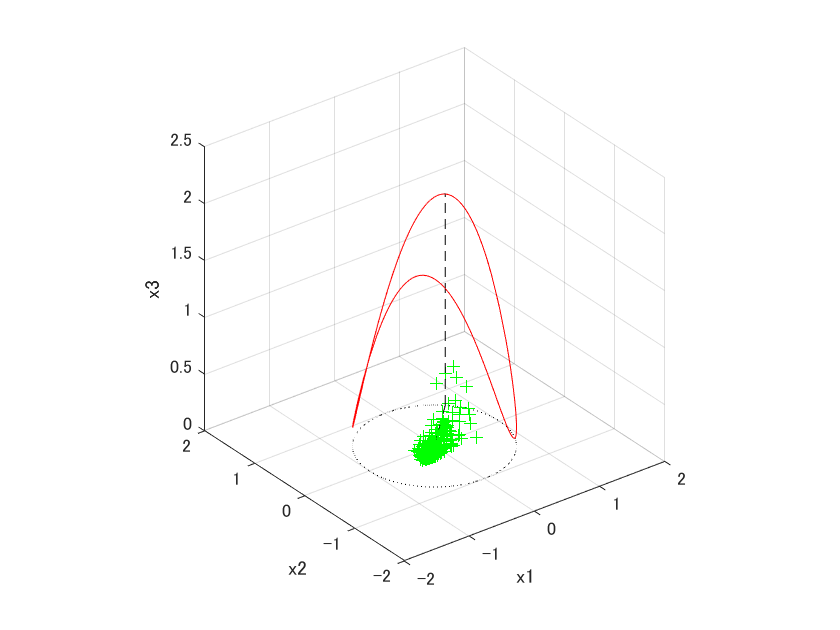

figure('Name','Fig.3-5: Visualazation of S=(u,Vu)');
xcirc = [-1:0.01:1]';
ycirc1 = sqrt(1-xcirc.^2);
ycirc2 = -sqrt(1-xcirc.^2);
for ii = 1:length(xcirc)
    zcirc1(ii) = [xcirc(ii) ycirc1(ii)]*V*[xcirc(ii) ycirc1(ii)]';
end
for ii = 1:length(xcirc)
    zcirc2(ii) = [xcirc(ii) ycirc2(ii)]*V*[xcirc(ii) ycirc2(ii)]';
end
plot3(xcirc,ycirc1,zcirc1,'r-'); hold on; plot3(xcirc,ycirc2,zcirc2,'r-'); axis square;
plot3(xcirc,ycirc1,zeros(size(zcirc1)),'k:'); plot3(xcirc,ycirc2,zeros(size(zcirc2)),'k:');
xlim([-2 2]); ylim([-2 2]); zlim([0 2.5]); grid on;
xlabel('x1'); ylabel('x2'); zlabel('x3');
scatter3(X(1,:)*0.3,X(2,:)*0.3,zeros(size(X(1,:))),'g+');
% pca
[coef,score,latent] = pca(X');
arrow3([0 0 0], [coef(:,1)' 0], 'k--',0);
arrow3([coef(:,1)' 0], [coef(:,1)' latent(1)],'k--',0);

図の赤い曲線が，$S=\left(u,\mathit{Vu}\right)$で定義される分散です．ただし，$u=\left\lbrack \begin{array}{c}
{\mathrm{u}}_1 \\
{\mathrm{u}}_2 
\end{array}\right\rbrack$とし，${\left\|u\right\|}^2 ={{\mathrm{u}}_1 }^2 +{{\mathrm{u}}_2 }^2 =1$です．また，${\mathrm{u}}_1$を${\mathrm{x}}_1$軸，${\mathrm{u}}_2$を${\mathrm{x}}_2$軸にとっています．また，緑色の十字はデータの各観測を表します．赤い曲線は，${\mathrm{x}}_1 {\mathrm{x}}_2$平面上の単位ベクトル$u=\left\lbrack \begin{array}{c}
{\mathrm{u}}_1 \\
{\mathrm{u}}_2 
\end{array}\right\rbrack$が示す方向におけるデータの分散を表します．データがもっとも広がっている方向において，赤い曲線$S=\left(u,\mathit{Vu}\right)$が最大になっているのが見て取れます（黒点線）．

## 分散の最大化と分散共分散行列の固有値分解

冒頭で予告したように，データの分散を最大限に含む主軸（第一主成分）と固有ベクトルおよび固有値の関係を具体的に見ていきます．ここでは，固有ベクトルおよび固有値の計算方法については言及せずに（計算方法については後述します），MATLABの標準関数eig()を用いて固有ベクトルと固有値を求めます．その後，それらがデータの分散を最大限に含む方向（主軸）を表し，その方向における分散と一致することをグラフを用いて確認します．

### eig()関数による固有ベクトルと固有値

まずは，eig()関数を用いて分散共分散行列の固有ベクトルと固有値を求めます．

[Q, D] = eig(V)

Q =     0.7071   -0.7071
   -0.7071   -0.7071


D =     0.1338         0
         0    1.8601


ここでは，２つの出力引数を$Q,D$としています．$Q$は２行２列の行列になっており，各列が固有ベクトルです．また，$D$も２行２列の行列になっています．ただし，行列$D$の非対角成分はいずれも$0$になっています．このような行列を対角行列といいます．$D$の対角成分はそれぞれ固有値と呼ばれ，$Q$の各列に対応します．すなわち，$D$の一行一列目の固有値と$Q$の一列目の固有ベクトルが対応し，$D$の二行二列目の固有値と$Q$の二列目の固有ベクトルが対応します（詳しくは，固有ベクトルおよび固有値の計算方法で説明します）．

今後の説明のために，固有値を左上から右下にかけて降順に並び替ます．

[d,ind] = sort(diag(D),'descend');
D = diag(d)

D =     1.8601         0
         0    0.1338


固有ベクトルも対応するように，$Q$の列を左側から順次並べ替えていきます．

Q = Q(:,ind)

Q =    -0.7071    0.7071
   -0.7071   -0.7071


eig関数の出力と，並べ替えた結果を見比べておいてください．

### pca()関数との比較

ここで，行列$Q$の各列すなわち固有ベクトルと行列$D$の対角成分を，pca()関数の第一出力引数および第三出力引数と比較してみます．データの分散を最大限に含む主軸を表します．前述したように，pca()関数の第一出力引数は主成分係数とよばれ，その各列は主軸方向を示す単位ベクトルです．また，pca()関数の第三出力引数は主成分分散と呼ばれ，各主軸方向に含まれる分散です．

比較のためにpca()関数を用いて主成分係数と主成分分散を求めておきます．

[coefs, ~, latents] = pca(X','Algorithm','eig')

coefs =     0.7071   -0.7071
    0.7071    0.7071


latents =     1.8658
    0.1342


ここで，pca()関数に渡すデータ行列は，行が観測，列が変数になっていなければいけないのでデータ行列$X$を転地しています．

つぎに比較のためにグラフを作成します（図５－１）．

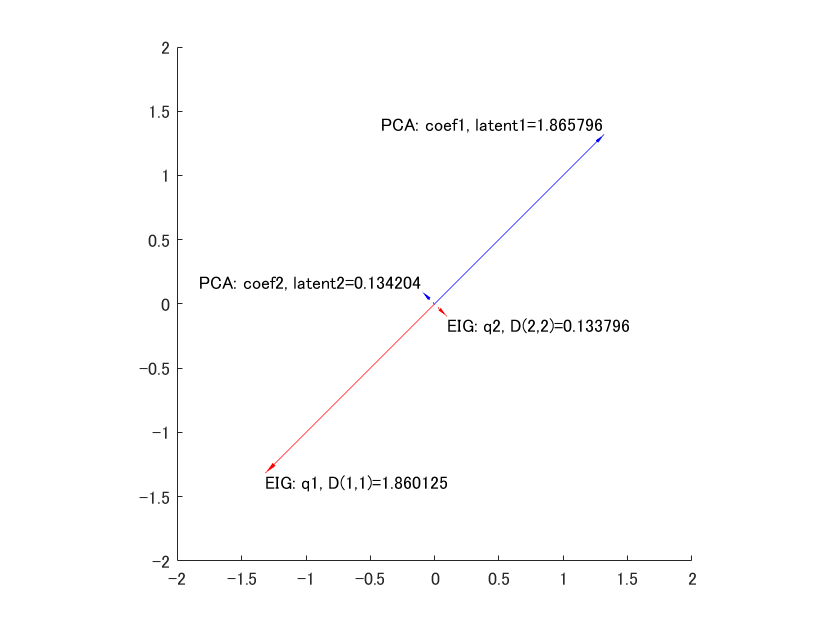

figure('Name','Fig.5-1: eig() vs. pca()');
arrow3([0 0], Q(:,1)'*D(1,1),'r-',1); hold on; % the 1st column of Q
str_q1 = sprintf('EIG: q1, D(1,1)=%f',D(1,1)); text(Q(1,1)*D(1,1),Q(2,1)*D(1,1),str_q1,'HorizontalAlignment','Left','VerticalAlignment','Top');
arrow3([0 0], Q(:,2)'*D(2,2),'r:',1); % the 2nd column of Q
str_q2 = sprintf('EIG: q2, D(2,2)=%f',D(2,2)); text(Q(1,2)*D(2,2),Q(2,2)*D(2,2),str_q2,'HorizontalAlignment','Left','VerticalAlignment','Top')
arrow3([0 0], coefs(:,1)'*latents(1),'b-',1); % the 1st column of coefs
str_coef1 = sprintf('PCA: coef1, latent1=%f',latents(1)); text(coefs(1,1)*latents(1),coefs(2,1)*latents(1),str_coef1,'HorizontalAlignment','Right','VerticalAlignment','Bottom');
arrow3([0 0], coefs(:,2)'*latents(2),'b:',1); % the 2nd column of coefs
str_coef2 = sprintf('PCA: coef2, latent2=%f',latents(2)); text(coefs(1,2)*latents(2),coefs(2,2)*latents(2),str_coef2,'HorizontalAlignment','Right','VerticalAlignment','bottom');
axis([-2 2 -2 2]); axis square;

eig()関数の第一出力引数$Q$の各列を赤色矢印で表しています．第一列の方向を実線（q1）で示し，その長さを第二出力引数$D$の１行１列目の成分と対応させています．第二列の方向は点線（q2）で示し，その長さを行列$D$の２行２列目の成分と対応させています．

pca()関数の第一出力引数（主成分係数行列）coefsの各列は青色矢印で表しています．第一列の方向を実線（coef1）で示し，第二出力引数（主成分分散）latentsの第一成分をその長さと対応させています．coefsの第二列の方向は点線（coef2）で示し，その長さはlatentsの第二成分と対応させています．

eig()関数における$Q$の一列目（赤実線矢印，q1）は，pca()関数における一つ目の主成分係数（青実線矢印，coef1）と同じ方向（向きは真逆）を表します．また，それらの長さ（eig()関数における$D$の一行一列目とpca()関数における一つ目の主成分分散）はほぼ同じです．同様に，行列$Q$の二列目（赤点線矢印，q2）と二つ目の主成分係数（青点線矢印，coef2）は同じ方向を示し，それらの長さ（$D$の二行二列目と二つ目の主成分分散）はほぼ等しくなっています．

前述したように，pca()関数の第一出力引数は主成分係数とよばれ，その各列は主軸方向を示す単位ベクトルです．また，pca()関数の第三出力引数は主成分分散と呼ばれ，各主軸方向に含まれる分散です．したがって，$Q$の第一列目はPCAの第一主成分に一致し，そのベクトルが示す方向において最大の分散が含まれます．また，そのときの分散の値は$1\ldotp 8601$です．さらに，$Q$の第一列目は第二列目と直行しており，その向きに含まれる分散は$0\ldotp 1338$です．

### 固有ベクトルおよび固有値の幾何学的解釈

正射影ベクトルの長さの分散のグラフを用いて，分散共分散行列$V$の固有ベクトルと固有値の幾何学な解釈を説明します．

データ行列$X$の任意の方向における分散のグラフは以下のようになります．

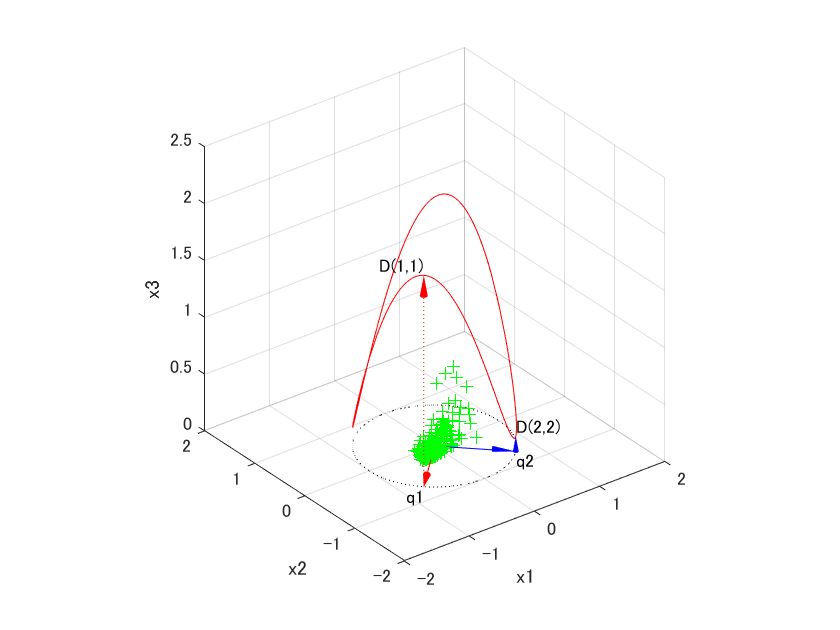

figure('Name','Fig.5-2: Visualazation of S=(u,Vu)');
xcirc = [-1:0.01:1]';
ycirc1 = sqrt(1-xcirc.^2);
ycirc2 = -sqrt(1-xcirc.^2);
for ii = 1:length(xcirc)
    zcirc1(ii) = [xcirc(ii) ycirc1(ii)]*V*[xcirc(ii) ycirc1(ii)]';
end
for ii = 1:length(xcirc)
    zcirc2(ii) = [xcirc(ii) ycirc2(ii)]*V*[xcirc(ii) ycirc2(ii)]';
end
figure('Name','Fig.3-5: S=(u,V) where (u,u)=1');
plot3(xcirc,ycirc1,zcirc1,'r-'); hold on; plot3(xcirc,ycirc2,zcirc2,'r-'); axis square;
plot3(xcirc,ycirc1,zeros(size(zcirc1)),'k:'); plot3(xcirc,ycirc2,zeros(size(zcirc2)),'k:');
xlim([-2 2]); ylim([-2 2]); zlim([0 2.5]); grid on;
xlabel('x1'); ylabel('x2'); zlabel('x3');
%view([-30.31 42.34]);
scatter3(X(1,:)*0.3,X(2,:)*0.3,zeros(size(X(1,:))),'g+');
% add eigen vectors and eign values
arrow3([0 0 0], [Q(:,1)' 0],'r-'); 
text(Q(1,1),Q(2,1),0,'q1','HorizontalAlignment','right','VerticalAlignment','top');
arrow3([Q(:,1)' 0],[Q(:,1)' D(1,1)],'r:');
text(Q(1,1),Q(2,1),D(1,1),'D(1,1)','HorizontalAlignment','right','VerticalAlignment','bottom');
arrow3([0 0 0],[Q(:,2)' 0],'b-');
text(Q(1,2),Q(2,2),0,'q2','HorizontalAlignment','left','VerticalAlignment','top');
arrow3([Q(:,2)' 0],[Q(:,2)' D(2,2)], 'b:');
text(Q(1,2),Q(2,2),D(2,2),'D(2,2)','HorizontalAlignment','left','VerticalAlignment','bottom');

行列$Q$の一列目すなわち一つ目の固有ベクトルが示す方向を赤色の実線矢印（q1）で表します．また対応する固有値の大きさを$\mathrm{x3}$軸方向に表します（D(1,1)）．一つ目の固有ベクトルはデータの分散が最大となる方向を示し，対応する固有値は分散の最大値と一致します．また，二つ目の固有ベクトル（行列$Q$の二列目，青色実線矢印，q2）は，一つ目の固有ベクトルと直交しており，そのときの分散は最小となっています（D(2,2)）．

## 固有ベクトルと固有値の求め方

このセクションではデータ行列$X$で表される二変量データを例にして，固有ベクトルと固有値の求め方を具体的に解説します．また，固有ベクトルと固有値による固有分解を紹介します．

### 固有ベクトルと固有値の定義

まず，固有ベクトルおよび固有値の定義を紹介します．一般に，正方行列$A$に対して，


$$\begin{array}{l}
\mathit{Ap}=\lambda p\\
p\not= 0
\end{array}$$


が成立するようなベクトル$p$を，行列$A$の固有ベクトルといいます．また，このときのスカラー$\lambda$を固有値といいます．

### 固有値の求め方

それでは，行列$A$に前述の分散共分散行列$V$を当てはめ，$A=V=\left\lbrack \begin{array}{cc}
0\ldotp 9970 & 0\ldotp 8632\\
0\ldotp 8632 & 0\ldotp 9970
\end{array}\right\rbrack$として，具体的に固有ベクトルおよび固有値を求めていきます．つまり，


$$\mathit{Vp}=\lambda p$$


を満たすようなゼロベクトルでないベクトル$p$と，スカラー$\lambda$を求めます．まず固有値$\lambda$を求めるために，上式を以下のように変形します．


$$\left(V-\lambda I\right)p=0$$


ここで，$I$は$V$と同じサイズの単位行列です．


$$\left(V-\lambda I\right)p=0$$


任意のベクトル$p\left(\not= 0\right)$に対して上式が成立するためには，


$$\textrm{det}\left(V-\lambda I\right)=0$$


が常に成立する必要があります．ここで記号$\mathrm{det}$は行列式を表します．$V$と$I$にそれぞれ具体的な値を代入すると，


$$\begin{array}{l}
\mathrm{det}\left(\left\lbrack \begin{array}{cc}
0\ldotp 9970 & 0\ldotp 8632\\
0\ldotp 8632 & 0\ldotp 9970
\end{array}\right\rbrack -\lambda \left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack \right)=0\\
\mathrm{det}\left(\left\lbrack \begin{array}{cc}
0\ldotp 9970-\lambda  & 0\ldotp 8632\\
0\ldotp 8632 & 0\ldotp 9970-\lambda 
\end{array}\right\rbrack \right)=0\\
{\left(0\ldotp 9970-\lambda \right)}^2 -{0\ldotp 8632}^2 =0\\
\left(0\ldotp 9970-\lambda -0\ldotp 8632\right)\left(0\ldotp 9970-\lambda +0\ldotp 8632\right)=0\\
\left(\lambda -0\ldotp 1338\right)\left(\lambda -1\ldotp 8602\right)=0
\end{array}$$


となり，固有値$\lambda$は1.8602および0.1338となります．eig()関数で求めた対角行列$D$の対角成分と一致することを確認してください．

D

D =     1.8601         0
         0    0.1338


今後の説明のために，$\lambda_1 =1\ldotp 8602$，$\lambda_2 =0\ldotp 1338$とします．なお，$n\times n$の正方行列に対しては$n$個の固有値が求まります．

### 固有ベクトルの求め方

つぎに，固有ベクトルを求めていきます．二つの固有値$\lambda_1$および$\lambda_2$はいずれも，


$$\left(V-\lambda I\right)p=0$$


を満たします．固有値の値で場合分けをして，それぞれの固有値に対応する固有ベクトルを求めていきます．

1) $\lambda =\lambda_1 \left(=1\ldotp 8061\right)$のとき

$p=\left\lbrack \begin{array}{c}
{\mathrm{p}}_1 \\
{\mathrm{p}}_2 
\end{array}\right\rbrack$として，上式を成分で表記すると以下のようになります．


$$\begin{array}{l}
\left(\left\lbrack \begin{array}{cc}
0\ldotp 9970 & 0\ldotp 8632\\
0\ldotp 8632 & 0\ldotp 9970
\end{array}\right\rbrack -1\ldotp 8601\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack \right)\left\lbrack \begin{array}{c}
{\mathrm{p}}_1 \\
{\mathrm{p}}_2 
\end{array}\right\rbrack =0\\
\left\lbrack \begin{array}{cc}
-0\ldotp 8631 & 0\ldotp 8632\\
0\ldotp 8632 & -0\ldotp 8632
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\mathrm{p}}_1 \\
{\mathrm{p}}_2 
\end{array}\right\rbrack =0\\
\left\lbrack \begin{array}{c}
-0\ldotp 8631{\mathrm{p}}_1 +0\ldotp 8632{\mathrm{p}}_2 \\
0\ldotp 8632{\mathrm{p}}_1 -0\ldotp 8631{\mathrm{p}}_2 
\end{array}\right\rbrack =0
\end{array}$$


これは，${\mathrm{p}}_1 ,{\mathrm{p}}_2$に関する線形連立方程式


$$\left\lbrace \begin{array}{cc}
-0\ldotp 8631{\mathrm{p}}_1 +0\ldotp 8632{\mathrm{p}}_2 =0 & \left(1\right)\\
0\ldotp 8632{\mathrm{p}}_1 -0\ldotp 8631{\mathrm{p}}_2 =0 & \left(2\right)
\end{array}\right.$$


を表します．これを${\mathrm{p}}_2$について解くと


$$\left\lbrace \begin{array}{cc}
{\mathrm{p}}_2 =\frac{0\ldotp 8631}{0\ldotp 8632}{\mathrm{p}}_1  & \left(1\right)\prime \\
{\mathrm{p}}_2 =\frac{0\ldotp 8632}{0\ldotp 8631}{\mathrm{p}}_1  & \left(2\right)\prime 
\end{array}\right.$$


となり，いずれも${\mathrm{p}}_2 \approx {\mathrm{p}}_1$となりほとんど同じ式になってしまいます．一般に，連立方程式の解は二つの式で表される直線の交点の座標として求めることができます．二つの式が同じになってしまう場合，交点は無数に存在し，一意の解を求めることはできません．また，二つの式が限りなく同じ直線を表す場合も，数値計算で解くことは難しくなります．実際に，上記の式が表す直線をグラフすると以下のようになります．

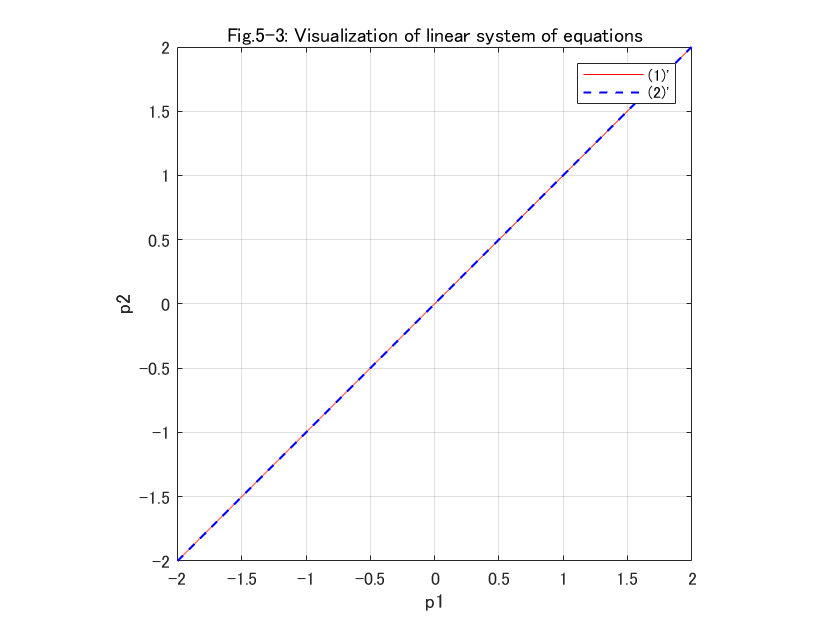

figure('Name','Fig.5-3: Visualazation of linear system of equations');
p1 = -2:2;
p2_1 = (0.8631/0.8632)*p1;
p2_2 = (0.8632/0.8631)*p1;
plot(p1,p2_1,'r-'); hold on; grid;
plot(p1,p2_2,'b--','LineWidth',1);
axis([-2 2 -2 2]); axis square;
legend('(1)''','(2)''');
title('Fig.5-3: Visualization of linear system of equations');
xlabel('p1'); ylabel('p2');

式$\left(1\right)\prime$および式$\left(2\right)\prime$はそれぞれ赤実線と青破線で示しています．二つの直線はほとんど重なっているのがわかります．このような場合，数値計算では解けないことがあります．実際にMATLABのlinsolve()関数で解いてみましょう．linsolve()関数は線型方程式の解を求める関数です．

N = V - D(1,1)*eye(2);
M = [0; 0];
p = linsolve(N,M)

p =      0
     0


上記のように警告が出て，解はゼロベクトルになってしまいます．そこで$\left\|p\right\|=\sqrt{{{\mathrm{p}}_1 }^2 +{{\mathrm{p}}_2 }^2 }=1$を制約条件にして，再度，上の連立方程式を解いてみましょう．求めるべき解は，式$\left(1\right)\prime$および式$\left(2\right)\prime$が示す直線と，${{\mathrm{p}}_1 }^2 +{{\mathrm{p}}_2 }^2 =1$が示す単位円の交点になります．それらをグラフにすると以下のようになります．

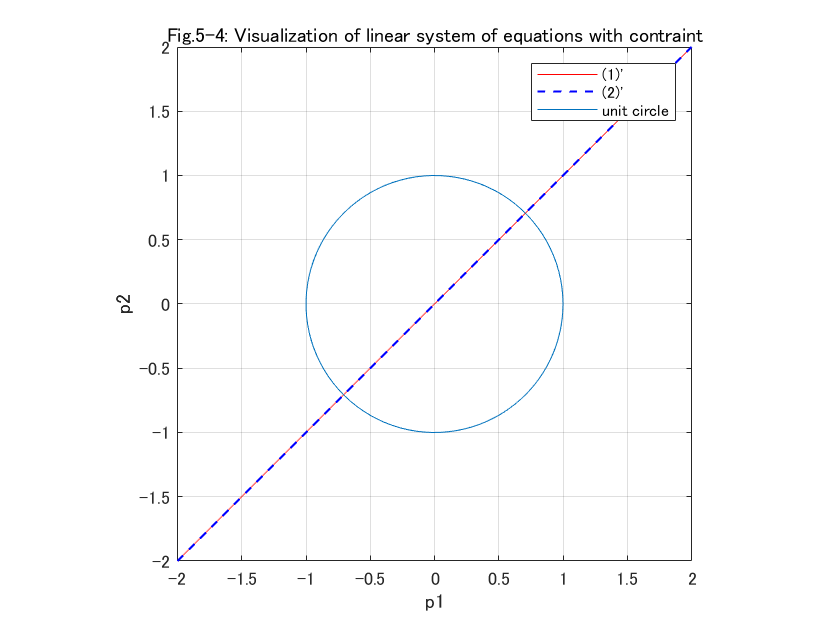

figure('Name','Fig.5-4: Visualazation of linear system of equations with contraint');
p1 = -2:2;
p2_1 = (0.8631/0.8632)*p1;
p2_2 = (0.8632/0.8631)*p1;
t = linspace(0,2*pi,100);
plot(p1,p2_1,'r-'); hold on; grid;
plot(p1,p2_2,'b--','LineWidth',1);
plot(cos(t),sin(t));
axis([-2 2 -2 2]); axis square;
legend('(1)''','(2)''','unit circle');
title('Fig.5-4: Visualization of linear system of equations with contraint');
xlabel('p1'); ylabel('p2');

水色の円が単位円を表します．この直線と曲線（円）の交点が求めるべき解です．解は二つ出てくることがわかります．向きは重要ではないので，ここでは解の範囲を${\mathrm{p}}_2 <0$に絞って方程式を解いていきます．MATLABのSymbolic Math Toolboxを使って解いてみましょう．

syms p1 p2;
eqn1 = p1 - p2 == 0;
eqn2 = p1^2 + p2^2 == 1;
equations = [eqn1 eqn2];
vars = [p1 p2];
range = [NaN NaN; -100 0];
sol = vpasolve(equations,vars,range);
p = [sol.p1; sol.p2]

$$p = \left(\begin{array}{c} -0.70710678118654752440084436210485\\ -0.70710678118654752440084436210485 \end{array}\right)$$

分散共分散行列$V$の一つ目の固有ベクトル（行列$Q$の一列目）と一致します．

Q

Q =    -0.7071    0.7071
   -0.7071   -0.7071


念のために，求められた解を先程の図の中に示してみます．

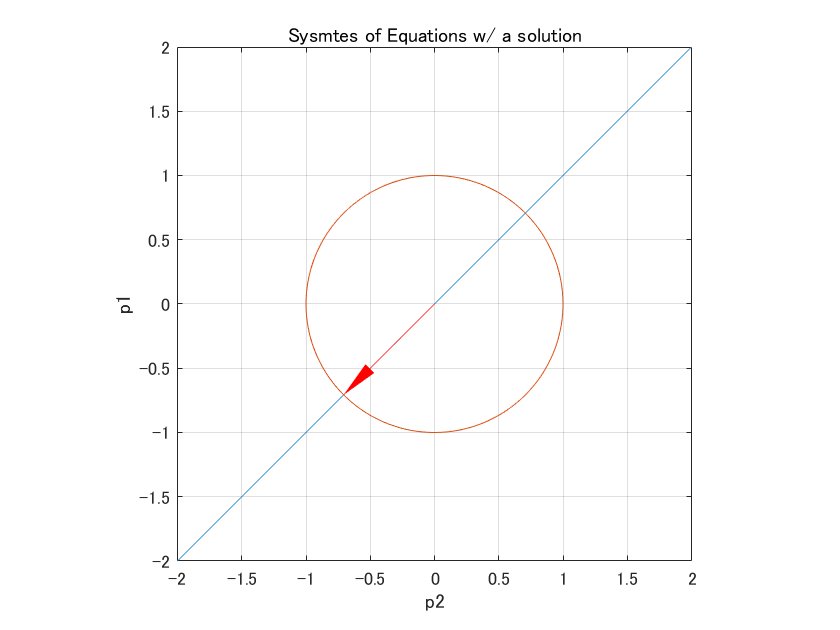

figure('Name','Fig.5-5: Sysmtes of Equations w/ a solution')
fimplicit(equations);
axis square; axis([-2 2 -2 2]); grid on;
title('Sysmtes of Equations w/ a solution'); ylabel('p1'); xlabel('p2'); 
q1 = double(p);
hold on; arrow3([0 0], q1','r');

図中の赤矢印が固有ベクトルが指し示す位置を表します．直線と単位円の交点を指しているのがわかります．

以上で固有値$\lambda_1 =1\ldotp 8601$に対応する（単位）固有ベクトルを求めることができました．この固有ベクトルを


$$q^{\left(1\right)} =\left\lbrack \begin{array}{c}
-0\ldotp 7071\\
-0\ldotp 7071
\end{array}\right\rbrack$$


とします．

2) ${\lambda =\lambda }_2 \left(=0\ldotp 1338\right)$のとき

次に固有値が$0\ldotp 1338$のときの固有ベクトルを求めていきます．このとき，固有ベクトル$\left\lbrack \begin{array}{c}
{\mathrm{p}}_1 \\
{\mathrm{p}}_2 
\end{array}\right\rbrack$は


$$\left(\left\lbrack \begin{array}{cc}
0\ldotp 9970 & 0\ldotp 8632\\
0\ldotp 8632 & 0\ldotp 9970
\end{array}\right\rbrack -0\ldotp 1338\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack \right)\left\lbrack \begin{array}{c}
{\mathrm{p}}_1 \\
{\mathrm{p}}_2 
\end{array}\right\rbrack =0$$


を満たします．これをまとめると，


$$\begin{array}{l}
\left\lbrack \begin{array}{cc}
0\ldotp 8632 & 0\ldotp 8632\\
0\ldotp 8632 & 0\ldotp 8632
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\mathrm{p}}_1 \\
{\mathrm{p}}_2 
\end{array}\right\rbrack =0\\
\left\lbrack \begin{array}{c}
0\ldotp 8632{\mathrm{p}}_1 +0\ldotp 8632{\mathrm{p}}_2 \\
0\ldotp 8632{\mathrm{p}}_1 +0\ldotp 8632{\mathrm{p}}_2 
\end{array}\right\rbrack =0
\end{array}$$


となり，いずれも


$${\mathrm{p}}_2 =-{\mathrm{p}}_1$$


となり，解を一意に求めることはできません．そこでさきほどと同様に，$\left\|p\right\|=\sqrt{{{\mathrm{p}}_1 }^2 +{{\mathrm{p}}_2 }^2 }=1$を制約条件にして方程式を解いてみましょう．まずは解を図示してみます．

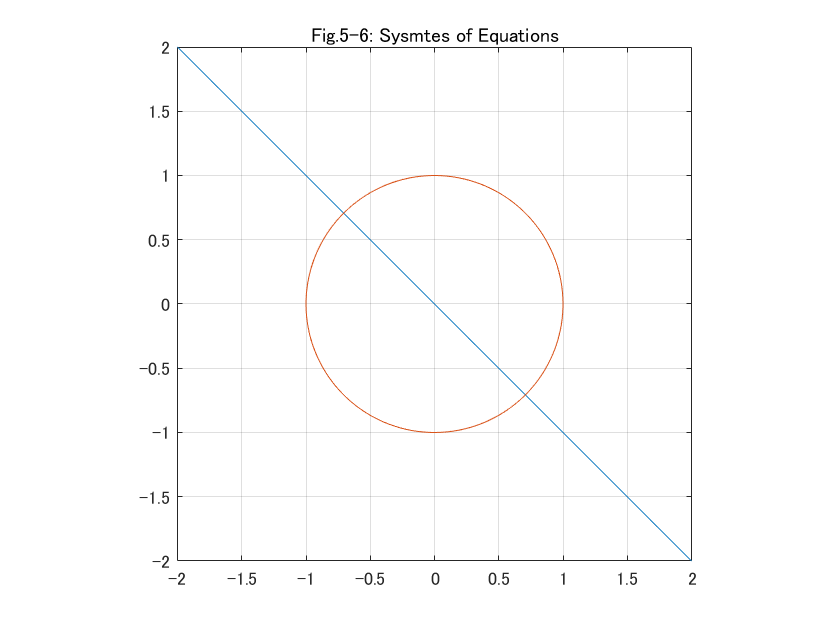

figure('Name','Fig.5-6: Sysmtes of Equations');
syms p1 p2;
eqn1 = p1 + p2 == 0;
eqn2 = p1^2 + p2^2 == 1;
equations = [eqn1 eqn2];
fimplicit(equations);
axis square; axis([-2 2 -2 2]); grid on;
title('Fig.5-6: Sysmtes of Equations');

直線と単位円は２点で交わり，解は２つ存在することがわかります．今度も，解の範囲を${\mathrm{p}}_2 <0$にしぼります．

vars = [p1 p2];
range = [NaN NaN; -100 0];
sol = vpasolve(equations,vars,range);
p = [sol.p1; sol.p2]

$$p = \left(\begin{array}{c} 0.70710678118654752440084436210485\\ -0.70710678118654752440084436210485 \end{array}\right)$$

これは，分散共分散行列$V$の二つ目の固有ベクトル（行列$Q$の二列目）と一致します．

Q

Q =    -0.7071    0.7071
   -0.7071   -0.7071


念のために，求められた解を先程の図の中に示します．

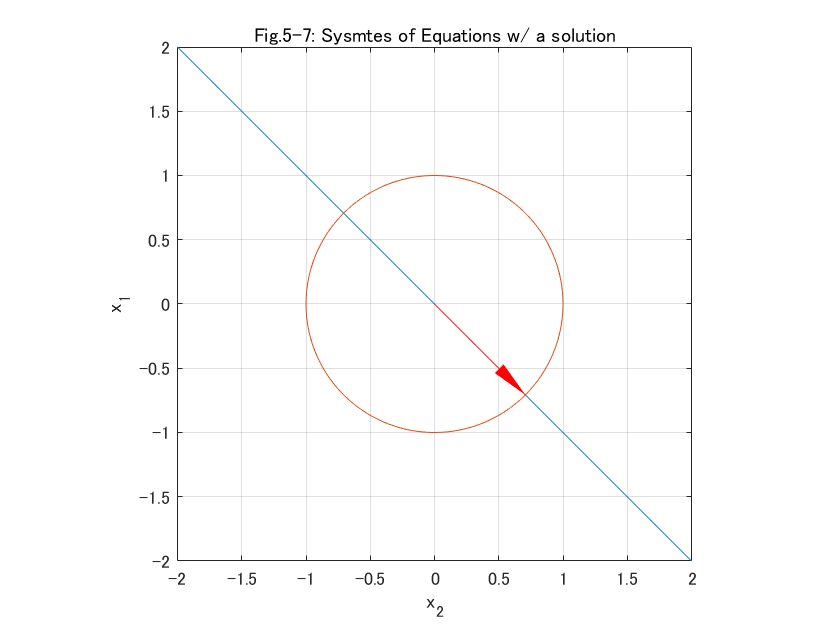

figure('Name','Fig.5-7: Sysmtes of Equations w/ a solution')
fimplicit(equations);
axis square; axis([-2 2 -2 2]); grid on;
title('Fig.5-7: Sysmtes of Equations w/ a solution'); ylabel('x_1'); xlabel('x_2'); 
q2 = double(p);
hold on; arrow3([0 0], q2','r');

以上で固有値$\lambda_2 =0\ldotp 7761$に対応する（単位）固有ベクトルを求めることができました．改めて，この固有ベクトルを

$q^{\left(2\right)} =\left\lbrack \begin{array}{c}
0\ldotp 7071\\
-0\ldotp 7071
\end{array}\right\rbrack$.

とします．

### 固有値分解

以上で，分散共分散行列$V$に対して固有ベクトルと固有値を求めることができました．結果をまとめると，二変量データ$X$に対する分散共分散行列$V$の固有値は二つあり，それぞれの固有値に対応する固有ベクトルは


$$\left\lbrace \begin{array}{cc}
q^{\left(1\right)} =\left\lbrack \begin{array}{c}
-0\ldotp 7071\\
-0\ldotp 7071
\end{array}\right\rbrack  & \left(\lambda =\lambda_1 =1\ldotp 8601\right)\\
q^{\left(2\right)} =\left\lbrack \begin{array}{c}
0\ldotp 7071\\
-0\ldotp 7071
\end{array}\right\rbrack  & \left(\lambda =\lambda_1 =0\ldotp 1338\right)
\end{array}\right.$$


となります．これらはいずれも，


$$V\lambda_i =\lambda_i q^{\left(i\right)} \;\left(i=1,2\right)$$


を満たします．ここで，前述のeig()関数の二つの出力$Q$および$D$はそれぞれ


$$\begin{array}{l}
Q=\left\lbrack \begin{array}{cc}
q^{\left(1\right)}  & q^{\left(2\right)} 
\end{array}\right\rbrack \\
D=\left\lbrack \begin{array}{cc}
\lambda_1  & 0\\
0 & \lambda_2 
\end{array}\right\rbrack 
\end{array}$$


と表すことができます．ただし，$Q$は$q^{\left(1\right)}$と$q^{\left(1\right)}$を各列に並べた行列です．このとき，


$$\left\lbrace \begin{array}{cc}
V\lambda_1 =\lambda_1 q^{\left(1\right)} \; & \left(*\right)\\
V\lambda_2 =\lambda_i q^{\left(2\right)} \; & \left(**\right)
\end{array}\right.$$


のふたつの式は，行列$Q$，$D$および分散共分散行列$V$をもちいて


$$\mathit{VQ}=\mathit{QD}$$


と表すことができます．行列$Q$の逆行列$Q^{-1}$を両辺に右からかけることで，分散共分散行列$V$について解くことができ


$$V=\mathit{QD}Q^{-1}$$


となります．分散共分散行列$V$がその固有ベクトルからなる行列$Q$と固有値からなる行列$D$に分解されて表現されます．これを分散共分散行列$V$の固有値分解といいます．

### 直交行列

上記の行列$Q$について重要な特徴を紹介します．対称行列の固有ベクトルを列方向に並べた行列$Q$は，以下のような性質をもちます．

- 各列が互いに直行

- 各行が互いに直行

- 転置行列が逆行列に等しい

- 行列式が$1$または$-1$

このような行列を直交行列といいます．以下で４つの性質について確認していきます．

#### 各列が互いに直交

まず一つ目の「各列が互いに直交する」ことを確かめてみます．直交するとは，ベクトルの内積がゼロになることです．実際に内積を計算してみると，

dot(Q(:,1),Q(:,2))

ans = 0

となり，各列は直交することがわかります（※１）．

#### 各行が互いに直交

同様に，「各行が直交する」ことを確かめます．

dot(Q(1,:),Q(2,:))

ans = 0

#### 転置行列と逆行列が等しい

直交行列$Q$の転置行列$Q^T$が行列$Q$の逆行列になっていることを確かめます．実際に計算してみると，

Q'*Q

ans =     1.0000    0.0000
    0.0000    1.0000


Q*Q'

ans =     1.0000   -0.0000
   -0.0000    1.0000


となり，$Q^T$が$Q$の逆行列になっていることがわかります（※２）．

#### 行列式は$\pm 1$

直交行列$Q$の転置行列と逆行列が等しいことから

    
$$QQ^T =Q^T Q=I$$


が常に成り立ちます．各辺の行列式


$$\mathrm{det}\left(QQ^T \right)=\mathrm{det}\left(Q^T Q\right)=\mathrm{det}\left(I\right)$$


となります．ここで，$\mathrm{det}\left(QQ^T \right)=\mathrm{det}\left(Q\right)\mathrm{det}\left(Q^T \right)$，$\mathrm{det}\left(Q^T Q\right)=\mathrm{det}\left(Q^T \right)\mathrm{det}\left(Q\right)$，$\mathrm{det}\left(I\right)=1$より，


$$\mathrm{det}\left(Q\right)\mathrm{det}\left(Q^T \right)=1$$


が成り立ちます．さらに，$\mathrm{det}\left(Q\right)=\mathrm{det}\left(Q^T \right)$より


$${\mathrm{det}\left(Q\right)}^2 =1$$


したがって，


$$\mathrm{det}\left(Q\right)=\pm 1$$


です．

#### ※１　対称行列の固有ベクトル

２行２列の対称行列$A$（$A^T =A$）の固有ベクトルを$q^{\left(1\right)}$および$q^{\left(2\right)}$として，ふたつの固有ベクトルが互いに直交することを示します．それぞれの固有ベクトルに対応する固有値を$\lambda_1$，$\lambda_2$（$\lambda_1 \not= \lambda_2$）とすると，


$$\begin{array}{l}
Aq^{\left(1\right)} =\lambda_1 q^{\left(1\right)} \\
Aq^{\left(2\right)} =\lambda_2 q^{\left(2\right)} 
\end{array}$$


が成立します．それぞれの式において，両辺の転地をとると


$$\begin{array}{l}
{q^{\left(1\right)} }^T A=\lambda_1 {q^{\left(1\right)} }^T \\
{q^{\left(2\right)} }^T A=\lambda_2 {q^{\left(2\right)} }^T 
\end{array}$$


となります．ただし，$A^T =A$としました．つぎに，ベクトル$q^{\left(1\right)}$と$Aq^{\left(2\right)}$の内積$\left(q^{\left(1\right)} ,Aq^{\left(2\right)} \right)$を二通りに式変形します．

まず，内積$\left(q^{\left(1\right)} ,Aq^{\left(2\right)} \right)$に$Aq^{\left(2\right)} =\lambda_2 q^{\left(2\right)}$を代入すると，


$$\left(q^{\left(1\right)} ,Aq^{\left(2\right)} \right)=\left(q^{\left(1\right)} ,\lambda_2 q^{\left(2\right)} \right)=\lambda_2 \left(q^{\left(1\right)} ,q^{\left(2\right)} \right)$$


となります．最後の式変形は$\lambda_2$がスカラーなので内積の外に出しました．つぎに，内積$\left(q^{\left(1\right)} ,Aq^{\left(2\right)} \right)$を以下のように変形します．


$$\left(q^{\left(1\right)} ,Aq^{\left(2\right)} \right)=\left({A^T q}^{\left(1\right)} ,q^{\left(2\right)} \right)=\left({\mathit{Aq}}^{\left(1\right)} ,q^{\left(2\right)} \right)$$


ここで，最左辺からの式変形には$\left(x,\mathit{Ay}\right)=\left(A^T x,y\right)$の関係を用いました．この関係が成り立つことは成分で書き下すとわかります．


$$\begin{array}{l}
\left(x,\mathit{Ay}\right)=\left(\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack ,\left\lbrack \begin{array}{cc}
{\mathrm{a}}_{11}  & {\mathrm{a}}_{12} \\
{\mathrm{a}}_{21}  & {\mathrm{a}}_{22} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\mathrm{y}}_1 \\
{\mathrm{y}}_2 
\end{array}\right\rbrack \right)=\left(\left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
{\mathrm{a}}_{11} \mathrm{y}+{\mathrm{a}}_{12} {\mathrm{y}}_2 \\
{\mathrm{a}}_{21} {\mathrm{y}}_1 +{\mathrm{a}}_{22} {\mathrm{y}}_2 
\end{array}\right\rbrack \right)={\mathrm{a}}_{11} {\mathrm{x}}_1 {\mathrm{y}}_1 +{\mathrm{a}}_{12} {\mathrm{x}}_1 {\mathrm{y}}_2 +{\mathrm{a}}_{21} {\mathrm{x}}_2 {\mathrm{y}}_1 +{\mathrm{a}}_{22} {\mathrm{x}}_2 {\mathrm{y}}_2 \\
\left(A^T x,y\right)=\left(\left\lbrack \begin{array}{cc}
{\mathrm{a}}_{11}  & {\mathrm{a}}_{21} \\
{\mathrm{a}}_{12}  & {\mathrm{a}}_{22} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\mathrm{x}}_1 \\
{\mathrm{x}}_2 
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
{\mathrm{y}}_1 \\
{\mathrm{y}}_2 
\end{array}\right\rbrack \right)=\left(\left\lbrack \begin{array}{c}
{\mathrm{a}}_{11} {\mathrm{x}}_1 +{\mathrm{a}}_{21} {\mathrm{x}}_2 \\
{\mathrm{a}}_{12} {\mathrm{x}}_1 +{\mathrm{a}}_{22} {\mathrm{x}}_2 
\end{array}\right\rbrack ,\left\lbrack \begin{array}{c}
{\mathrm{y}}_1 \\
{\mathrm{y}}_2 
\end{array}\right\rbrack \right)={\mathrm{a}}_{11} {\mathrm{x}}_1 {\mathrm{y}}_1 +{\mathrm{a}}_{21} {\mathrm{x}}_2 {\mathrm{y}}_1 +{\mathrm{a}}_{12} {\mathrm{x}}_1 {\mathrm{y}}_2 +{\mathrm{a}}_{22} {\mathrm{x}}_{2{\mathrm{y}}_2 } =\left(x,\mathit{Ay}\right)
\end{array}$$


さて，$\left({\mathit{Aq}}^{\left(1\right)} ,q^{\left(2\right)} \right)$に$Aq^{\left(1\right)} =\lambda_1 q^{\left(1\right)}$を代入すると，


$$\left({\mathit{Aq}}^{\left(1\right)} ,q^{\left(2\right)} \right)=\left(\lambda_1 q^{\left(1\right)} ,q^{\left(2\right)} \right)=\lambda_1 \left(q^{\left(1\right)} ,q^{\left(2\right)} \right)$$


となります．これで内積$\left(q^{\left(1\right)} ,Aq^{\left(2\right)} \right)$について二通りの式変形を得ました．


$$\left\lbrace \begin{array}{cc}
\left(q^{\left(1\right)} ,Aq^{\left(2\right)} \right)=\lambda_2 \left(q^{\left(1\right)} ,q^{\left(2\right)} \right) & \left(\mathrm{あ}\right)\\
\left(q^{\left(1\right)} ,Aq^{\left(2\right)} \right)=\lambda_1 \left(q^{\left(1\right)} ,q^{\left(2\right)} \right) & \left(\mathrm{い}\right)
\end{array}\right.$$


式（あ）から式（い）を引くと，


$$\begin{array}{l}
\lambda_2 \left(q^{\left(1\right)} ,q^{\left(2\right)} \right)-\lambda_1 \left(q^{\left(1\right)} ,q^{\left(2\right)} \right)=0\\
\left(\lambda_2 -\lambda_1 \right)\left(q^{\left(1\right)} ,q^{\left(2\right)} \right)=0
\end{array}$$


となります．ここで$\lambda_1 \not= \lambda_2$ですから，


$$\left(q^{\left(1\right)} ,q^{\left(2\right)} \right)=0$$


となり，ふたつの固有ベクトルは直交します．

#### ※２　直交行列と逆行列

直交行列$Q$の転置行列と逆行列が等しいことを示します．ここで$QQ^T$を考えると，


$$QQ^T =\left\lbrack \begin{array}{cc}
q^{\left(1\right)}  & q^{\left(2\right)} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{q^{\left(1\right)} }^T \\
{q^{\left(2\right)} }^T 
\end{array}\right\rbrack$$


と表すことができます．さらに変形すると，


$$QQ^T =\left\lbrack \begin{array}{cc}
{q^{\left(1\right)} }^T q^{\left(1\right)}  & {q^{\left(1\right)} }^T q^{\left(2\right)} \\
{q^{\left(2\right)} }^T q^{\left(1\right)}  & {q^{\left(2\right)} }^T q^{\left(2\right)} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\left(q^{\left(1\right)} ,q^{\left(1\right)} \right) & \left(q^{\left(1\right)} ,q^{\left(2\right)} \right)\\
\left(q^{\left(2\right)} ,q^{\left(1\right)} \right) & \left(q^{\left(2\right)} ,q^{\left(2\right)} \right)
\end{array}\right\rbrack$$


となります．それぞれの成分は内積になっています．ここで，ベクトル$q^{\left(i\right)}$が単位ベクトルであることと，互いに直交することから

    
$$\begin{array}{l}
\left(q^{\left(i\right)} ,q^{\left(i\right)} \right)={\left\|q^{\left(i\right)} \right\|}^2 =1\;\;\;\;\left(i=1,2\right)\\
\left(q^{\left(i\right)} ,q^{\left(j\right)} \right)=0\;\;\;\;\;\;\;\left(i\not= j\right)
\end{array}$$


が成り立ち，それらを代入すると，


$$QQ^T =\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack$$


となります．同様に，$Q^T Q$についても


$$Q^T Q=\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack$$


が成り立ちます．つまり，$Q^T$は行列$Q$の逆行列であり，


$$Q^{-1} =Q^T$$


です．

### 分散共分散の固有値分解

さて，分散共分散行列はその定義より，必ず対称行列になります．したがって，分散共分散$V$の固有値分解


$$V=\mathit{DQ}D^{-1}$$


において，行列$Q$は直交行列となりとなります．したがって，$Q^{-1} =Q^T$を満たすことから，分散共分散$V$の固有値分解は


$$V=\mathit{DQ}D^T$$


と表されます．

## これまでのまとめ

本章では，データ行列$X$の分散共分散行列$V$について，以下の２点を確認しました．

- PCAの主成分係数が，分散共分散行列$V$の固有ベクトルと一致する

- PCAの主成分分散は，分散共分散行列$V$の固有値と一致する

すなわち，データの分散をもっともよく説明する主軸は，データの分散共分散行列の固有ベクトルとして求めることができます．また，それぞれの主軸方向で説明される分散の量は，分散共分散行列の固有値として求めることができます．

次の章では，なぜ共分散行列の固有ベクトルが分散が最大となる方向やそれと直交する方向を示すのか，また，なぜ固有値がそれぞれの主軸方向で説明される分散となるのかを解説していきます．